# ATS Mandatory Assignment 05

% **Assignment 5 (Mandatory)**  
% **MatNr:6940188**
% **MatNr:**
% **Submission Date:** December 12th, 2025


## Task 1: Simulating an ARMA(1,1) Process

% **Objective:** Simulate and visualize an ARMA(1,1) process with t-distributed innovations.

%%% Task 1.1: Define the ARMA Simulator Function
% Create a MATLAB function to simulate an ARMA(1,1) process:
% \[
% y_t = c + \phi y_{t-1} + \epsilon_t + \theta \epsilon_{t-1}
% \]
% where \(\epsilon \sim t(\nu)\).

function yt = ARMA_simulator(T, c, phi, theta, nu, y0)
    % Inputs:
    % - T: Sample size (number of observations)
    % - c: Constant term
    % - phi: AR (autoregressive) parameter
    % - theta: MA (moving average) parameter
    % - nu: Degrees of freedom for the t-distributed innovations
    % - y0: Initial value for the process
    % Output:
    % - yt: Simulated time series

    % --- Initialize ---
    yt = zeros(T, 1); % Preallocate memory for the time series
    epsilon = trnd(nu, T, 1); % Generate t-distributed innovations
    yt(1) = y0; % Set initial value
    epsilon_prev = 0; % Initialize ε_{t-1} to 0

    % --- Generate ARMA(1,1) Process ---
    for t = 2:T
        % Recurrence relation for ARMA(1,1)
        yt(t) = c + phi * yt(t-1) + epsilon(t) + theta * epsilon_prev;
        epsilon_prev = epsilon(t); % Update ε_{t-1}
    end
end

%%% Task 1.2: Simulate the Process
% Simulate the ARMA(1,1) process with the specified parameters.

% --- Parameters ---
c = 2;              % Constant term in the model
phi = 0.95;         % AR (autoregressive) parameter
theta = 0.25;       % MA (moving average) parameter
nu = 4;             % Degrees of freedom for t-distributed innovations
T = 800;            % Total number of observations in the time series
y0 = 40;            % Initial value for the process (set to expected value)
burn_in = 50;       % Length of the burn-in phase to remove initial dependencies

% --- Expected Value ---
% Compute the expected value of the process based on the formula:
% E(y_t) = c / (1 - phi), where |phi| < 1 ensures stationarity.
expected_value = c / (1 - phi);
disp(['Expected Value: ', num2str(expected_value)]);

Expected Value: 40


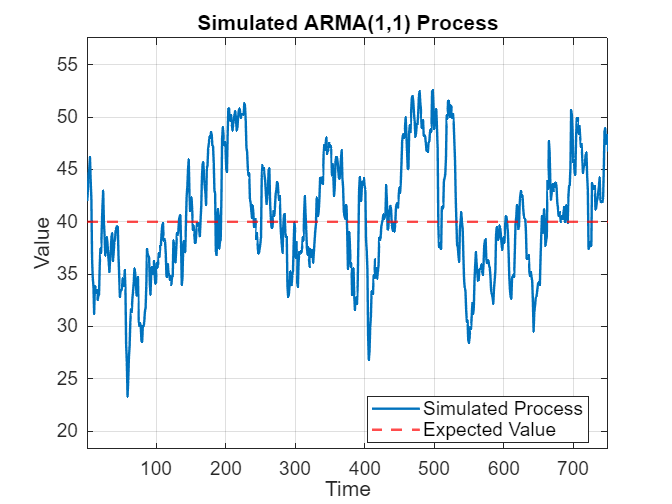


% --- Simulate the Process ---
% Use the ARMA_simulator function to generate the time series
rng(42);  % Set seed for reproducibility to ensure consistent results
series = ARMA_simulator(T, c, phi, theta, nu, y0);

% --- Remove Burn-in Phase ---
% Discard the first 50 observations to avoid artifacts from initialization.
y = series((burn_in + 1):end); % Final time series with 750 observations

%%% Task 1.3: Visualize the Process
% Visualize the simulated ARMA(1,1) process.

% --- Create Figure ---
figure; % Create a new figure window
hold on; % Allow multiple plots on the same figure

% --- Plot Time Series ---
% Plot the time series (after burn-in) with a specified line width and color
plot(1:(T - burn_in), y, 'LineWidth', 1.5, 'Color', [0 0.4470 0.7410]);

% --- Plot Expected Value ---
% Add the expected value as a horizontal dashed red line
yline(expected_value, '--r', 'LineWidth', 1.5, ...
    'LabelHorizontalAlignment', 'right', 'LabelVerticalAlignment', 'bottom');

% --- Customize Appearance ---
% Add title and labels with appropriate font sizes
title('Simulated ARMA(1,1) Process', 'FontSize', 14, 'FontWeight', 'bold');
xlabel('Time', 'FontSize', 12); % Label for x-axis
ylabel('Value', 'FontSize', 12); % Label for y-axis
grid on; % Enable grid for better visualization

% --- Adjust Axes Limits ---
% Set x-axis to span the length of the time series after burn-in
xlim([1 T - burn_in]); 
% Set y-axis to include a margin around the minimum and maximum values
ylim([min(y) - 5, max(y) + 5]);

% --- Add Legend ---
% Include a legend to label the components of the plot
legend({'Simulated Process', 'Expected Value'}, 'Location', 'best', 'FontSize', 12);

% --- Finalize Plot ---
set(gca, 'FontSize', 12, 'Box', 'on'); % Adjust axis properties
hold off; % Release the hold on the figure

## Task 2: Unit Root Tests

% **Objective:** Estimate the AR(1) model using OLS and perform the Dickey-Fuller test to examine stationarity.

%%% Task 2.2: Estimation of the Series with OLS
% Use Ordinary Least Squares (OLS) to estimate the parameters of the AR(1) model.

% --- Define Response Variable ---
yt = y(2:end); % Response variable (current values of the series, excluding the first observation)

% --- Define Lagged Variable ---
yt_lag = y(1:end-1); % Lagged variable (values shifted by one time step)

% --- Construct Design Matrix ---
% Add an intercept term and the lagged variable to form the design matrix X
X = [ones(length(yt_lag), 1), yt_lag];

% --- Compute OLS Estimates ---
% Calculate the OLS estimates using the formula: b = (X'X)^(-1)X'y
b = (X' * X) \ (X' * yt);

% --- Extract Parameters ---
alpha_hat = b(1); % Estimated intercept (drift term)
rho_hat = b(2);   % Estimated AR coefficient (ρ)

% --- Compute Predictions and Residuals ---
y_pred = X * b;          % Predicted values based on OLS estimates
residuals = yt - y_pred; % Residuals (difference between actual and predicted values)

% --- Estimate Variance of Residuals ---
% Variance of residuals: σ² = (1 / (n - k)) * Σ(residuals²)
% Adjusted for 2 parameters (intercept and slope)
s_squared = (1 / (length(yt) - 2)) * sum(residuals .^ 2);

% --- Compute Covariance Matrix ---
% Covariance matrix: Cov(b) = σ² * (X'X)^(-1)
Cov_b = s_squared * inv(X' * X);

% --- Compute Standard Errors ---
% Standard errors are the square root of the diagonal elements of the covariance matrix
s_errors = sqrt(diag(Cov_b));

% --- Extract Standard Errors ---
s_error_alpha = s_errors(1); % Standard error for intercept (α)
s_error_rho = s_errors(2);   % Standard error for AR coefficient (ρ)

% --- Display Results ---
disp('Estimated coefficients (βˆ):');

Estimated coefficients (βˆ):


disp(['c (constant): ', num2str(b(1))]); % Display intercept estimate

c (constant): 1.4638


disp(['φ (AR parameter): ', num2str(b(2))]); % Display AR coefficient estimate

φ (AR parameter): 0.96393


disp('Standard Errors (s.e.):');

Standard Errors (s.e.):


disp(['s.e.(c): ', num2str(s_error_alpha)]); % Display standard error of the intercept

s.e.(c): 0.40172


disp(['s.e.(φ): ', num2str(s_error_rho)]);   % Display standard error of the AR coefficient

s.e.(φ): 0.0098452



%%% Task 2.3: Perform Dickey-Fuller Test
% Test the null hypothesis (H0: ρ = 1) to check for a unit root.

% --- Calculate t-statistic ---
% t-statistic for testing H0: ρ = 1
phi_hat = b(2);         % Estimated AR coefficient
se_phi = s_errors(2);   % Standard error of the AR coefficient
t_stat = (phi_hat - 1) / se_phi; % Test statistic
disp(['t-statistic: ', num2str(t_stat)]);

t-statistic: -3.6633



% --- Compare with Critical Value ---
% Critical value for the test (example: -2.86 for a 5% significance level in the drift case)
critical_value = -2.86; 

% --- Make Decision ---
if t_stat < critical_value
    disp('Reject the null hypothesis (H0: φ = 1). The series is stationary.');
else
    disp('Fail to reject the null hypothesis (H0: φ = 1). The series is non-stationary.');
end

Reject the null hypothesis (H0: φ = 1). The series is stationary.


## Task 3: Constructing the Conditional Log Likelihood

%%% Helper functions for Task 3
% Loglikelihood contributions
function logL_contributions = ml_contributions(params, y)
    % ARMA(1,1) Conditional Log Likelihood Function with t-distributed Innovations
    %
    % INPUTS:
    %   params - A column vector of parameters [c; φ; θ; ν]
    %       c   - Constant term in the ARMA process
    %       φ   - AR parameter
    %       θ   - MA parameter
    %       ν   - Degrees of freedom for the t-distribution
    %   y      - A column vector of time series data [y1; y2; ...; yT]
    %
    % OUTPUT:
    %   logL_contributions - A ((T-1)×1) column vector of log likelihood contributions

    % Extract parameters
    c = params(1);
    phi = params(2);
    theta = params(3);
    nu = params(4);
    
    % Initialize variables
    T = length(y);
    epsilons = zeros(T, 1); % Innovations vector (ε_t)
    logL_contributions = zeros(T-1, 1); % Log likelihood contributions
    
    % Compute the series of innovations ε_t
    for t = 2:T
        epsilons(t) = y(t) - c - phi * y(t-1) - theta * epsilons(t-1);
    end

    % Drop ε1 (the first innovation)
    epsilons = epsilons(2:end);
    
    % Compute log likelihood contributions
    for t = 1:(T-1)
        % Compute the log likelihood contribution for each t
        logL_contributions(t) = gammaln((nu + 1) / 2) ...
                                - gammaln(nu / 2) ...
                                - 0.5 * log(nu * pi) ...
                                - (nu + 1) / 2 * log(1 + (epsilons(t)^2 / nu));
    end
end

%%% Second Helper function
% loglikelihood
function total_logL = loglikelihood(params, y)
    % Computes the total conditional log likelihood for an ARMA(1,1) process
    % with t-distributed innovations by calling the arma_conditional_log_likelihood function.
    %
    % INPUTS:
    %   params - A column vector of parameters [c; φ; θ; ν]
    %   y      - A column vector of time series data [y1; y2; ...; yT]
    %
    % OUTPUT:
    %   total_logL - The total conditional log likelihood value (scalar)
    
    % Call the arma_conditional_log_likelihood function
    logL_contributions = ml_contributions(params, y);
    
    % Compute the total log likelihood by summing the contributions
    total_logL = sum(logL_contributions);
end

% **Objective:** Compute the total conditional log likelihood for the ARMA(1,1) process
% using different sets of parameter values and the full series.

% --- Define the Series ---
% Use the full series (y) for evaluating the conditional log likelihood.
% y = series; % Simulated ARMA(1,1) series with 800 observations.

% --- Case (a) Parameters ---
% Parameters used to generate the series:
% c = 2, φ = 0.95, θ = 0.25, ν = 4
params_a = [2; 0.95; 0.25; 4];

% Compute the total log likelihood for case (a)
% The loglikelihood function evaluates the conditional log likelihood contributions.
total_logL_a = loglikelihood(params_a, y);

% Display the total log likelihood for case (a)
disp(['Total conditional log likelihood for case a): ', num2str(total_logL_a)]);

Total conditional log likelihood for case a): -1298.8673



% --- Case (b) Parameters ---
% Alternative parameters for comparison:
% c = 1.5, φ = 0.75, θ = 0.5, ν = 6
params_b = [1.5; 0.75; 0.5; 6];

% Compute the total log likelihood for case (b)
total_logL_b = loglikelihood(params_b, y);

% Display the total log likelihood for case (b)
disp(['Total conditional log likelihood for case b): ', num2str(total_logL_b)]);

Total conditional log likelihood for case b): -5515.3011


## Task 4: Parameter Estimation with Maximum Likelihood

% Helper function for task 4
function negLogL = neg_loglikelihood(params, y)
    % Computes the negative total conditional log likelihood for ARMA(1,1)
    % INPUTS:
    %   params - A column vector of parameters [c; φ; θ; ν]
    %   y      - A column vector of time series data [y1; y2; ...; yT]
    %
    % OUTPUT:
    %   negLogL - The negative total log likelihood (scalar)
    
    % Call the conditional log likelihood contributions function
    logL_contributions = ml_contributions(params, y);
    
    % Compute the total log likelihood and return its negative
    negLogL = -sum(logL_contributions);
end

% **Objective:** Estimate the parameters of the ARMA(1,1) process using Conditional Maximum Likelihood (CML).

% --- Add CML Toolbox to Path ---
% Include the CML toolbox in the working directory
addpath('CML\CML');

%%% Define Starting Values
% Initial parameter guesses:
% c0 = 1.5, φ0 = 0.75, θ0 = 0.5, ν0 = 5
x0 = [1.5; 0.75; 0.5; 5]; % Column vector for starting values

%%% Optimization Settings
% Define optimization parameters for fminsearch algorithm
options = optimset('Display', 'iter', 'TolX', 1e-40, 'TolFun', 1e-40, ...
                   'MaxIter', 1e10, 'MaxFunEvals', 100000);

% --- Functions for Optimization ---
% 1) `ml_contributions` calculates the conditional log likelihood contributions.
% 2) `neg_loglikelihood` calculates the negative log likelihood to be minimized.

% --- Specify Algorithm and Covariance ---
% algorithm = 1: fminsearch (derivative-free optimization)
% covPar = 1: Use Hessian-based covariance matrix

%%% Run CML Function
% Estimate parameters by minimizing the negative log likelihood
[x, f, g, cov, retcode] = CML(@neg_loglikelihood,   ...  % Function to minimize
                              @ml_contributions,    ...  % Log likelihood contributions
                              y,                    ...  % Dataset (series)
                              x0,                   ...  % Starting values
                              1,                    ...  % Algorithm (fminsearch)
                              1,                    ...  % Covariance type (Hessian-based)
                              options);             ...  % Optimization settings


 
 Iteration   Func-count         f(x)         Procedure
     0            1           5175.4         
     1            5          4454.83         initial simplex
     2            6          4454.83         reflect
     3            7          4454.83         reflect
     4            9          3809.91         expand
     5           11          2789.29         expand
     6           12          2789.29         reflect
     7           14          1616.25         expand
     8           16          1480.17         reflect
     9           18          1360.02         reflect
    10           19          1360.02         reflect
    11           21          1360.02         contract outside
    12           23          1360.02         contract inside
    13           25          1360.02         contract inside
    14           27          1360.02         contract inside
    15           29          1360.02         contract inside
    16           31          1354.59         contract ou

%%% Display Results
% Optimized parameter estimates
disp('Optimized parameters = ');

Optimized parameters = 


disp(x);

    2.2312
    0.9452
    0.2837
    3.4691




% Value of the minimum negative log likelihood
disp('Minimum negative log-likelihood = ');

Minimum negative log-likelihood = 


disp(f);

   1.2971e+03




% Gradient at the optimum
disp('Gradient at optimum = ');

Gradient at optimum = 


disp(g);

   1.0e-05 *

   -0.0004
   -0.3212
   -0.0003
   -0.0000




% Covariance matrix of parameter estimates
disp('Covariance matrix of estimates = ');

Covariance matrix of estimates = 


disp(cov);

    0.1683   -0.0041    0.0031    0.0030
   -0.0041    0.0001   -0.0001   -0.0001
    0.0031   -0.0001    0.0010   -0.0001
    0.0030   -0.0001   -0.0001    0.1298




% Exit flag indicating convergence status
disp(['Exit flag from fminsearch = ', num2str(retcode)]);

Exit flag from fminsearch = 1



%%% Extract Results
% Store the optimized parameters and covariance matrix
paramEst = x;      % Estimated parameters [c; φ; θ; ν]
covEst = cov;      % Covariance matrix of parameter estimates

%%% Compute Standard Errors
% Standard errors are the square roots of the diagonal elements of the covariance matrix
SE = sqrt(diag(covEst));

%%% Construct 95% Confidence Intervals
% 95% confidence intervals: [estimate ± 1.96 * standard error]
zVal = 1.96; % Z-value for 95% CI
CI_lower = paramEst - zVal .* SE;
CI_upper = paramEst + zVal .* SE;

% --- Display Results with Confidence Intervals ---
paramNames = {'c', 'phi', 'theta', 'nu'};
fprintf('\nParameter Estimates with 95%% CIs:\n');


Parameter Estimates with 95% CIs:


for i = 1:length(paramEst)
    fprintf('%s: Estimate = %.4f, SE = %.4f, CI = [%.4f, %.4f]\n', ...
        paramNames{i}, paramEst(i), SE(i), CI_lower(i), CI_upper(i));
end

c: Estimate = 2.2312, SE = 0.4102, CI = [1.4271, 3.0352]
phi: Estimate = 0.9452, SE = 0.0100, CI = [0.9255, 0.9648]
theta: Estimate = 0.2837, SE = 0.0309, CI = [0.2231, 0.3443]
nu: Estimate = 3.4691, SE = 0.3603, CI = [2.7630, 4.1752]



%%% Task 4.4: Perform t-test for H0: φ = 0.8
% Test the null hypothesis H0: φ = 0.8 at a 5% significance level (two-sided test)
phiEst = paramEst(2); % Estimated φ
phiSE = SE(2);        % Standard error of φ

% Compute the t-statistic
tStat = (phiEst - 0.8) / phiSE;

% Critical value for a 5% two-sided test
critVal = 1.96;

% Display test results
fprintf('\nT-test for H0: phi = 0.8\n');


T-test for H0: phi = 0.8


fprintf('   Estimate of phi = %.4f\n', phiEst);

   Estimate of phi = 0.9452


fprintf('   Standard Error   = %.4f\n', phiSE);

   Standard Error   = 0.0100


fprintf('   Test statistic   = %.4f\n', tStat);

   Test statistic   = 14.4996



if abs(tStat) > critVal
    fprintf('   => Reject H0 at the 5%% level (|tStat| > 1.96).\n\n');
else
    fprintf('   => Fail to reject H0 at the 5%% level.\n\n');
end

   => Reject H0 at the 5% level (|tStat| > 1.96).



%%% Task 4.5: Compute Two-Sided p-Value
% Compute the two-sided p-value for the t-statistic
pValue = 2 * (1 - normcdf(abs(tStat))); % Two-sided p-value
fprintf('Test statistic for H0: phi = 0.8 is tStat = %.4f\n', tStat);

Test statistic for H0: phi = 0.8 is tStat = 14.4996


fprintf('Two-sided p-value = %.6f\n', pValue);

Two-sided p-value = 0.000000



% Interpretation of p-value
if pValue < 0.05
    fprintf('=> p-value < 0.05 => Reject H0 at 5%% level.\n\n');
else
    fprintf('=> p-value >= 0.05 => Fail to reject H0 at 5%% level.\n\n');
end

=> p-value < 0.05 => Reject H0 at 5% level.




%%% Task 4.6: Simulate with T = 50,000
% Simulate a longer ARMA(1,1) series (T = 50,000) and re-estimate parameters.

% --- Parameters for Simulation ---
c = 2;              % Constant term
phi = 0.95;         % AR parameter
theta = 0.25;       % MA parameter
nu = 4;             % Degrees of freedom for t-distribution
T = 50000;          % Total length of the series
y0 = c / (1 - phi); % Starting value (expected value of the process)

% Simulate the ARMA(1,1) process
rng(200); % Set seed for reproducibility
series = ARMA_simulator(T, c, phi, theta, nu, y0);

% Update the series for analysis
y = series((burn_in+1):end);

% --- Re-estimate Parameters ---
% Use the same initial values and optimization settings
[x, f, g, cov, retcode] = CML(@neg_loglikelihood,   ...
                              @ml_contributions,    ...
                              y,                    ...
                              x0,                   ...
                              1,                    ...
                              1,                    ...
                              options);

 
 Iteration   Func-count         f(x)         Procedure
     0            1           342176         
     1            5           293880         initial simplex
     2            6           293880         reflect
     3            7           293880         reflect
     4            9           250820         expand
     5           11           182647         expand
     6           12           182647         reflect
     7           14           105248         expand
     8           16          96628.2         reflect
     9           18          89095.2         reflect
    10           19          89095.2         reflect
    11           21          89095.2         contract outside
    12           23          89095.2         contract inside
    13           25          89095.2         contract inside
    14           27          89095.2         contract inside
    15           29          89095.2         contract inside
    16           31          88586.9         contract ou


% Display results
disp('Optimized parameters = ');

Optimized parameters = 


disp(x);

    1.9638
    0.9510
    0.2426
    3.9736




disp('Minimum negative log-likelihood = ');

Minimum negative log-likelihood = 


disp(f);

   8.4208e+04




disp('Gradient at optimum = ');

Gradient at optimum = 


disp(g);

   1.0e-05 *

    0.0001
   -0.3011
   -0.0113
   -0.0004




disp('Covariance matrix of estimates = ');

Covariance matrix of estimates = 


disp(cov);

    0.0023   -0.0001    0.0000    0.0000
   -0.0001    0.0000   -0.0000   -0.0000
    0.0000   -0.0000    0.0000   -0.0000
    0.0000   -0.0000   -0.0000    0.0030




disp(['Exit flag from fminsearch = ', num2str(retcode)]);

Exit flag from fminsearch = 1



%%% Confidence Intervals for New Estimates
paramEst = x;      % New parameter estimates
covEst = cov;      % Covariance matrix
SE = sqrt(diag(covEst)); % Standard errors
CI_lower = paramEst - zVal .* SE;
CI_upper = paramEst + zVal .* SE;

fprintf('\nParameter Estimates with 95%% CIs (T = 50,000):\n');


Parameter Estimates with 95% CIs (T = 50,000):


for i = 1:length(paramEst)
    fprintf('%s: Estimate = %.4f, SE = %.4f, CI = [%.4f, %.4f]\n', ...
        paramNames{i}, paramEst(i), SE(i), CI_lower(i), CI_upper(i));
end

c: Estimate = 1.9638, SE = 0.0482, CI = [1.8692, 2.0583]
phi: Estimate = 0.9510, SE = 0.0012, CI = [0.9487, 0.9533]
theta: Estimate = 0.2426, SE = 0.0037, CI = [0.2353, 0.2500]
nu: Estimate = 3.9736, SE = 0.0550, CI = [3.8658, 4.0814]


## Task 5: Quasi-Maximum Likelihood

% task 5 1st helper function
% qml contributions
function logL_contributions = qml_contributions(params, y)
    % ml_contributions_gaussian:
    %   Computes the per-observation log-likelihood contributions for an
    %   ARMA(1,1) model with Gaussian (N(0, sigma^2)) innovations.
    %
    % Model:
    %   y_t = c + phi * y_{t-1} + epsilon_t + theta * epsilon_{t-1},
    %   where  epsilon_t ~ N(0, sigma^2).
    %
    % INPUTS:
    %   params - A 4x1 column vector [c; phi; theta; sigma2],
    %            where sigma2 is the variance (not the st.dev.)
    %   y      - A column vector of time series data [y1; y2; ...; yT].
    %
    % OUTPUT:
    %   logL_contributions - A (T-1)x1 vector of per-observation log-likelihoods.

    % Extract parameters
    c      = params(1);
    phi    = params(2);
    theta  = params(3);
    sigma2 = params(4);


    T = length(y);
    epsilons = zeros(T, 1);

    % Compute the series of innovations:
    %   epsilon_t = y_t - c - phi*y_{t-1} - theta*epsilon_{t-1}
    for t = 2:T
        epsilons(t) = y(t) - c - phi*y(t-1) - theta*epsilons(t-1);
    end

    % Drop the first innovation (t=1 has no "previous" y or epsilon)
    epsilons = epsilons(2:end); % => size (T-1)x1

    % Compute log-likelihood contributions for Gaussian:
    %   ln f(epsilon_t) = -0.5*ln(2*pi*sigma^2) - (epsilon_t^2)/(2*sigma^2)
    logL_contributions = -0.5 * log(2*pi*sigma2) ...
                         - 0.5 * (epsilons.^2 ./ sigma2);
end

% second helper function
% qml_l
function total_logL = qml_l(params, y)
    % loglikelihood_gaussian:
    %   Sums the per-observation log-likelihood contributions for an
    %   ARMA(1,1) model with Gaussian innovations.
    %
    % INPUTS:
    %   params - A 4x1 column vector [c; phi; theta; sigma2]
    %   y      - A column vector of time series data [y1; y2; ...; yT]
    %
    % OUTPUT:
    %   total_logL - The total conditional log-likelihood (scalar).

    % Get the contributions from the helper function
    logL_contributions = qml_contributions(params, y);

    % Sum over t = 2..T
    total_logL = -sum(logL_contributions);
end



T=800;
rng(42);  % Set seed for reproducibility to ensure consistent results
series = ARMA_simulator(T, c, phi, theta, nu, y0);

% Update the series for analysis
y = series((burn_in+1):end);
% y = series; % Time series realization from Task 1

%%% Define Starting Values
% Initial parameter guesses:
% c_0 = 1.5, φ_0 = 0.75, θ_0 = 0.5, σ²_0 = 1
x0 = [1.5; 0.75; 0.5; 1]; % Starting values (variance σ² replaces ν)

%%% Set Optimization Options
% Optimization settings for fminsearch:
% - TolX: Tolerance for parameter convergence
% - TolFun: Tolerance for function value convergence
% - MaxIter: Maximum number of iterations
% - MaxFunEvals: Maximum number of function evaluations
options = optimset('Display', 'iter', ...
                   'TolX', 1e-40, ...
                   'TolFun', 1e-40, ...
                   'MaxIter', 1e10, ...
                   'MaxFunEvals', 100000);

%%% Algorithm and Covariance Matrix
% Specify the algorithm and covariance matrix type:
% - algorithm = 1: fminsearch (derivative-free optimization)
% - covPar = 3: QML-based covariance matrix (accounts for misspecification)
algorithm = 1; % fminsearch
covPar = 3;    % QML-based covariance

%%% Run the CML Toolbox
% Pass the QML functions (negative log likelihood and contributions) to the CML toolbox
[x_qml, fval_qml, g_qml, cov_qml, retcode_qml] = ...
    CML(@qml_l,                    ...  % Function to minimize
        @qml_contributions,        ...  % Log likelihood contributions
        y,                         ...  % Dataset (series)
        x0,                        ...  % Starting values
        algorithm,                 ...  % Algorithm type
        covPar,                    ...  % Covariance matrix type
        options);                  ...  % Optimization settings


 
 Iteration   Func-count         f(x)         Procedure
     0            1            14044         
     1            5          10014.5         initial simplex
     2            6          10014.5         reflect
     3            7          10014.5         reflect
     4            9          7409.04         expand
     5           11          4385.59         expand
     6           12          4385.59         reflect
     7           14          1833.73         expand
     8           16          1646.99         reflect
     9           18          1569.93         reflect
    10           19          1569.93         reflect
    11           21          1569.93         contract inside
    12           23          1569.93         contract outside
    13           25          1569.93         contract inside
    14           27          1549.91         contract inside
    15           29          1531.15         contract inside
    16           31          1515.15         contract in

%%% Inspect Results
% Display the results of the QML estimation:
fprintf('QML results (Gaussian assumption) for ARMA(1,1):\n');

QML results (Gaussian assumption) for ARMA(1,1):



% Estimated parameters: [c; φ; θ; σ²]
fprintf('Estimated parameters:\n');

Estimated parameters:


disp(x_qml);

    2.2499
    0.9445
    0.2955
    2.1237




% Minimum value of the negative log likelihood
fprintf('Negative Log-Likelihood at optimum = %.4f\n', fval_qml);

Negative Log-Likelihood at optimum = 1344.8390



% Gradient of the objective function at the optimum
fprintf('Gradient at optimum:\n');

Gradient at optimum:


disp(g_qml);

   1.0e-05 *

    0.0002
   -0.1668
    0.0045
    0.0008




% Covariance matrix of the parameter estimates (QML-based)
fprintf('Covariance matrix (QML-based):\n');

Covariance matrix (QML-based):


disp(cov_qml);

    0.2074   -0.0050    0.0033   -0.0011
   -0.0050    0.0001   -0.0001    0.0000
    0.0033   -0.0001    0.0012    0.0005
   -0.0011    0.0000    0.0005    0.0291




% Exit flag indicating optimization status
fprintf('Exit flag: %d\n', retcode_qml);

Exit flag: 1


## Task 6: Comparing ML and QML

% **Objective:** Simulate K = 2500 realizations of the ARMA(1,1) process, estimate parameters 
% using both Maximum Likelihood (ML) and Quasi-Maximum Likelihood (QML), and compare the results.

%%% Task 6a: Simulate and Estimate Parameters
% --- Parameters from Task 1 ---
c = 2;              % Constant term
phi = 0.95;         % AR parameter
theta = 0.25;       % MA parameter
nu = 4;             % Degrees of freedom for t-distribution
T = 800;            % Total series length
burn_in = 50;       % Burn-in phase length to discard initial dependencies
K = 2500;           % Number of ensemble simulations
y0 = 40;            % Initial value for the process

% --- Storage for Estimates ---
ML_estimates = zeros(K, 4);       % To store ML estimates: [c, phi, theta, nu] (Kx4)
QML_estimates = zeros(K, 4);      % To store QML estimates: [c, phi, theta, sigma^2] (Kx4)
ML_covariances = zeros(K, 4, 4);  % To store ML covariance matrices (Kx4x4)
ML_standard_errors = zeros(K, 4); % To store ML standard errors (sqrt of diagonal of covariance matrices)

% --- Starting Values for Estimation ---
x0_ML = [1.5; 0.75; 0.5; 5];  % Initial guesses for ML: [c0, phi0, theta0, nu0]
x0_QML = [1.5; 0.75; 0.5; 1]; % Initial guesses for QML: [c0, phi0, theta0, sigma^2_0]

% --- Optimization Settings ---
% Define optimization settings for both ML and QML estimation
options = optimset('Display', 'off', 'TolX', 1e-40, 'TolFun', 1e-40, ...
                   'MaxIter', 1e10, 'MaxFunEvals', 100000);
algorithm = 1;      % Use fminsearch for optimization
covPar_ML = 1;      % Hessian-based covariance matrix for ML
covPar_QML = 3;     % QML-based covariance matrix for QML

% --- Loop Over K Simulations ---
for k = 1:K
    % --- Step 1: Simulate ARMA(1,1) Process ---
    % Generate a new realization of the ARMA(1,1) process
    series = ARMA_simulator(T, c, phi, theta, nu, y0);
    y = series((burn_in + 1):end);  % Remove burn-in phase (resulting in 750 observations)

    % --- Step 2: Estimate Parameters with ML (t-distributed) ---
    % Estimate parameters assuming t-distributed innovations
    [ML_params, ~, ~, ML_cov, ~] = CML(@neg_loglikelihood, ...
                                       @ml_contributions, ...
                                       y, x0_ML, algorithm, covPar_ML, options);
    ML_estimates(k, :) = ML_params';               % Store ML estimates
    ML_covariances(k, :, :) = ML_cov;              % Store covariance matrix
    ML_standard_errors(k, :) = sqrt(diag(ML_cov))';% Store standard errors

    % --- Step 3: Estimate Parameters with QML (Gaussian) ---
    % Estimate parameters assuming Gaussian innovations
    [QML_params, ~, ~, ~, ~] = CML(@qml_l, ...
                                   @qml_contributions, ...
                                   y, x0_QML, algorithm, covPar_QML, options);
    QML_estimates(k, :) = QML_params';             % Store QML estimates
end

% --- Output Completion ---
disp('Simulation and estimation complete.');

Simulation and estimation complete.


disp('ML estimates, QML estimates, and ML standard errors stored.');

ML estimates, QML estimates, and ML standard errors stored.


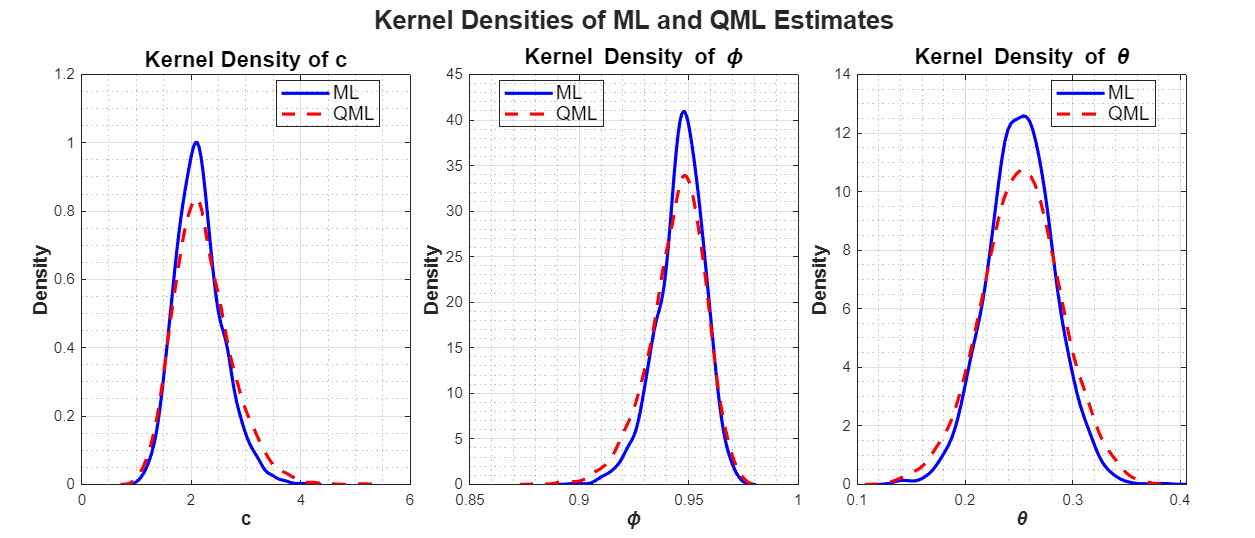


%%% Task 6b: Kernel Density Estimation and Visualization
% Compare distributions of ML and QML estimates for parameters c, phi, and theta.

% --- Parameter Labels ---
% Labels for parameters to be displayed in plots
params = {'c', '\phi', '\theta'};  

% --- Plot Formatting ---
% Define colors and line styles for ML and QML estimates
colors = {'b', 'r'};        % Blue for ML, Red for QML
lineStyles = {'-', '--'};   % Solid for ML, Dashed for QML

% --- Create Figure ---
% Create a new figure for kernel density plots
figure('Color', 'w', 'Position', [100, 100, 1400, 600]); % Adjust figure size

% --- Define Tiled Layout ---
% Requires MATLAB R2019b or later for tiledlayout
t = tiledlayout(1, 3, 'TileSpacing', 'Compact', 'Padding', 'Compact');

% --- Loop Over Parameters ---
for i = 1:3  % Loop over parameters: c (1), phi (2), theta (3)
    nexttile;  % Move to the next tile

    % --- Compute Kernel Density Estimates (KDE) ---
    [ML_density, ML_x] = ksdensity(ML_estimates(:, i));   % KDE for ML estimates
    [QML_density, QML_x] = ksdensity(QML_estimates(:, i));% KDE for QML estimates

    % --- Plot ML Estimates ---
    plot(ML_x, ML_density, 'LineWidth', 2, 'Color', colors{1}, 'LineStyle', lineStyles{1});
    hold on;

    % --- Plot QML Estimates ---
    plot(QML_x, QML_density, 'LineWidth', 2, 'Color', colors{2}, 'LineStyle', lineStyles{2});

    % --- Format Plot ---
    title(['Kernel Density of ', params{i}], 'FontSize', 14, 'FontWeight', 'bold'); % Add title
    xlabel(params{i}, 'FontSize', 12, 'FontWeight', 'bold'); % Label x-axis
    ylabel('Density', 'FontSize', 12, 'FontWeight', 'bold'); % Label y-axis

    % --- Add Legend ---
    legend({'ML', 'QML'}, 'Location', 'Best', 'FontSize', 12, 'Color', 'none');

    % --- Customize Grid ---
    grid on;
    grid minor;

    hold off;
end

% --- Add Super Title ---
% Add a title to the entire figure for better context
sg = sgtitle('Kernel Densities of ML and QML Estimates', 'FontSize', 16, 'FontWeight', 'bold');


% --- Adjust Title Position ---
% Fine-tune the position of the super title
current_pos = sg.Position;

Unrecognized method, property, or field 'Position' for class 'matlab.graphics.layout.Text'.

sg.Position = [current_pos(1), current_pos(2) + 0.05, current_pos(3)];

## Task 7: Confidence Interval Analysis

% **Objective:** Compute 95% confidence intervals (CIs) for ML estimates across K simulations 
% and determine the proportion of true parameters falling within these intervals.

% True parameter values (used for simulation)
true_params = [2; 0.95; 0.25; 4]; % [c, φ, θ, ν]

% Extract ML estimates and standard errors
c_ML = ML_estimates(:, 1);
phi_ML = ML_estimates(:, 2);
theta_ML = ML_estimates(:, 3);
nu_ML = ML_estimates(:, 4);

se_c = ML_standard_errors(:, 1);
se_phi = ML_standard_errors(:, 2);
se_theta = ML_standard_errors(:, 3);
se_nu = ML_standard_errors(:, 4);

% Compute 95% confidence intervals
lower_c = c_ML - 1.96 * se_c;
upper_c = c_ML + 1.96 * se_c;

lower_phi = phi_ML - 1.96 * se_phi;
upper_phi = phi_ML + 1.96 * se_phi;

lower_theta = theta_ML - 1.96 * se_theta;
upper_theta = theta_ML + 1.96 * se_theta;

lower_nu = nu_ML - 1.96 * se_nu;
upper_nu = nu_ML + 1.96 * se_nu;

% Test how often true parameters lie within the confidence intervals
c_in_CI = sum((true_params(1) >= lower_c) & (true_params(1) <= upper_c));
phi_in_CI = sum((true_params(2) >= lower_phi) & (true_params(2) <= upper_phi));
theta_in_CI = sum((true_params(3) >= lower_theta) & (true_params(3) <= upper_theta));
nu_in_CI = sum((true_params(4) >= lower_nu) & (true_params(4) <= upper_nu));

% Compute percentages
c_coverage = (c_in_CI / 2500) * 100;
phi_coverage = (phi_in_CI / 2500) * 100;
theta_coverage = (theta_in_CI / 2500) * 100;
nu_coverage = (nu_in_CI / 2500) * 100;

% Display results
disp('95% Confidence Interval Coverage Results:');

95% Confidence Interval Coverage Results:


disp('-----------------------------------------');

-----------------------------------------


fprintf('Parameter c (true value = %.2f): %.2f%% of intervals include the true value\n', true_params(1), c_coverage);

Parameter c (true value = 2.00): 94.08% of intervals include the true value


fprintf('Parameter φ (true value = %.2f): %.2f%% of intervals include the true value\n', true_params(2), phi_coverage);

Parameter φ (true value = 0.95): 94.08% of intervals include the true value


fprintf('Parameter θ (true value = %.2f): %.2f%% of intervals include the true value\n', true_params(3), theta_coverage);

Parameter θ (true value = 0.25): 94.12% of intervals include the true value


fprintf('Parameter ν (true value = %.2f): %.2f%% of intervals include the true value\n', true_params(4), nu_coverage);

Parameter ν (true value = 4.00): 95.76% of intervals include the true value


disp('-----------------------------------------');

-----------------------------------------
